# Scaling

## Strong Scaling


A = [1	0.013	1.80E-05 0.012982
     2	0.0078	4.10E-05 0.007759
     4	0.0046	9.60E-05 0.004504
     8	0.0028	5.30E-05 0.002747];

y = A(:,2)/A(1,2);
V = [ones(4,1) 1./A(:,1)];
x = V\y;

seq = x(1) % Sequential fraction

seq = 0.1264

par = x(2) % Parallel fraction

par = 0.8872

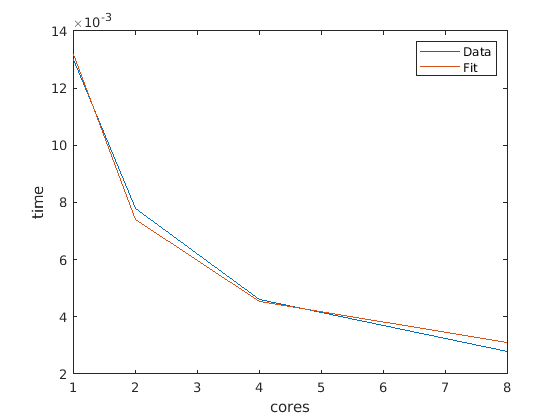

figure
plot(A(:,1),A(:,2),A(:,1),A(1,2)*(V*x))
legend('Data','Fit')
xlabel('cores')
ylabel('time')

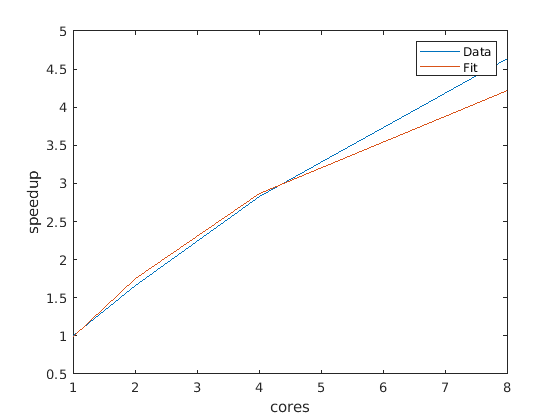

figure
plot(A(:,1),A(1,2)./A(:,2),A(:,1),1./(V*x))
xlabel('cores')
ylabel('speedup')
legend('Data','Fit')

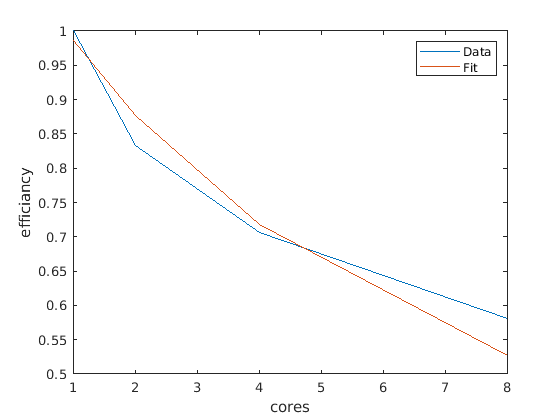

figure
plot(A(:,1),A(1,2)./A(:,2)./A(:,1),A(:,1),1./(V*x)./A(:,1))
xlabel('cores')
legend('Data','Fit')
ylabel('efficiancy')

## Weak Scaling

y = A(1,2)./A(:,2);
V = [ones(4,1) A(:,1)];
x = V\y;
seq = x(1)

seq = 0.6071

par = x(2)

par = 0.5138

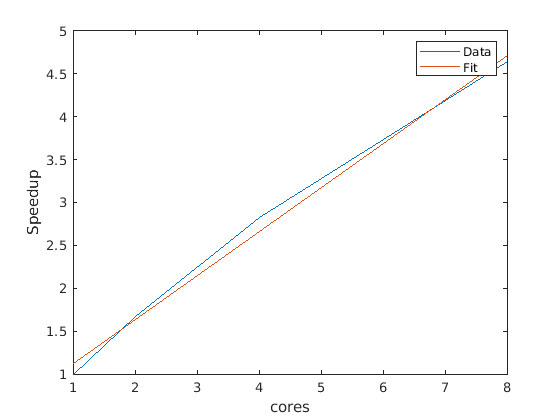

figure
plot(A(:,1),y,A(:,1),(V*x))
legend('Data','Fit')
xlabel('cores')
ylabel('Speedup')

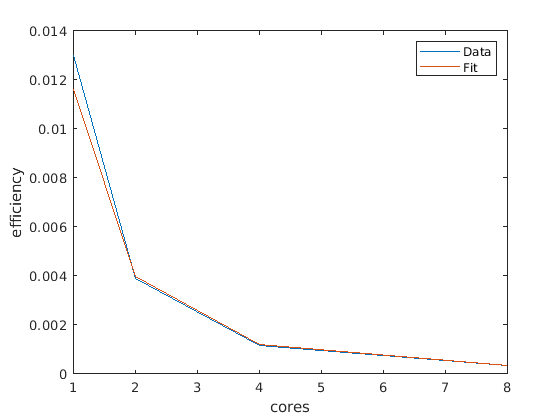

figure
plot(A(:,1),A(:,2)./A(:,1),A(:,1),A(1,2)./(V*x)./A(:,1))
legend('Data','Fit')
xlabel('cores')
ylabel('efficiency')

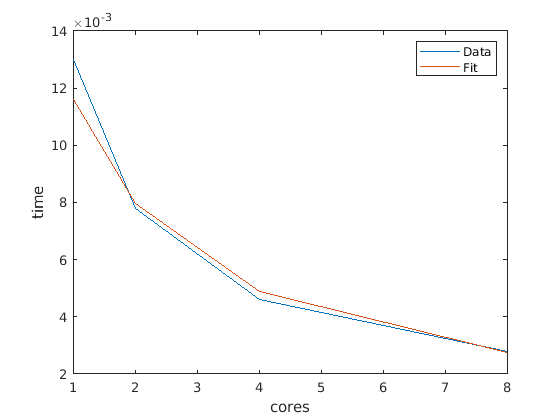


figure
plot(A(:,1),A(:,2),A(:,1),A(1,2)./(V*x))
legend('Data','Fit')
xlabel('cores')
ylabel('time')